# Image surface

The accommodative state of an eye is expressed in diopters (D). A given accommodation implies that points in object space, at a distance 1/D meters from the principal point of the eye, will be in optimal focus on the retina. This set of points in object space are distributed as on the surface of a sphere, and may be termed the object surface. For any given point from the object surface, we may obtain the internal focal point. The set of internal focal points that derive from the object surface form the *image surface*.

These ideas are discussed in:

- Liu, Tao, Vidhyapriya Sreenivasan, and Larry N. Thibos. "[Uniformity of accommodation across the visual field](https://jov.arvojournals.org/article.aspx?articleid=2488411)." *Journal of Vision* 16.3 (2016): 6-6.

- Verkicharla, Pavan K., et al. "Eye shape and retinal shape, and their relation to peripheral refraction." *Ophthalmic and Physiological Optics* 32.3 (2012): 184-199.

In this demonstration we will examine the image surface for an eye that is accommodated at specified distance. The default eye has stigmatic but centered optical elements.

First we create the eye, imaged at 555 nm.

accommodation = 1; % The accommodation of the eye in diopters
eye = modelEyeParameters('spectralDomain',555,'accommodation',accommodation);

When we define visual field positions below, we will do so with respect to these reference points:

incidentNode = eye.landmarks.incidentNode.coords;
principalPoint = calcPrincipalPoint(eye);
objectDistance = 1000/accommodation; % in mm

Generate and plot the optical system:

figure
plotOpticalSystem(eye,'newFigure',false);
hold on

Add a schematic outline of the eye and some labels

plotModelEyeSchematic(eye,'newFigure',false);
title('Image surface')
xlabel('axial [mm]'); ylabel('horizontal [mm]'); zlabel('vertical [mm]')

Now loop over visual field positions and plot the focal points, color coded by the distance with which the focal point misses the surface of the retina

S = eye.retina.S;
eFP = []; % external focal point
iFP = []; % internal focal point
cFP = []; % symbol plot color
Drel = []; % Accommodation of a retinal point relative to the vertex
Dref = calcAccommodation(eye,[0 0],incidentNode); % Accommodation at the vertex
maxEccen = 30;
deltaDeg = 2.5;
for hh = -maxEccen:deltaDeg:maxEccen
    for vv = -maxEccen:deltaDeg:maxEccen
        if norm([hh vv])>maxEccen
            continue
        end
        Drel(end+1) = calcAccommodation(eye,[hh vv],incidentNode)-Dref;
        [iFP(:,end+1),~,rp] = calcInternalFocalPoint(eye,[hh vv],objectDistance,incidentNode,principalPoint);
        eFP(:,end+1)=rp(:,1); % store the external focal point
        if Drel(end) <=-0.1 % Create color codes for errors
            % Relative myopia (blue-green)
            cFP(end+1,:) = [0 min([1 -Drel(end)]) 1];
        elseif Drel(end) >= 0.1
            % relative hyperopia (red-yellow)
            cFP(end+1,:) = [1 min([1 Drel(end)]) 0];
        else
            cFP(end+1,:) = [0.5 0.5 0.5];
        end
    end
end

Add the image surface 

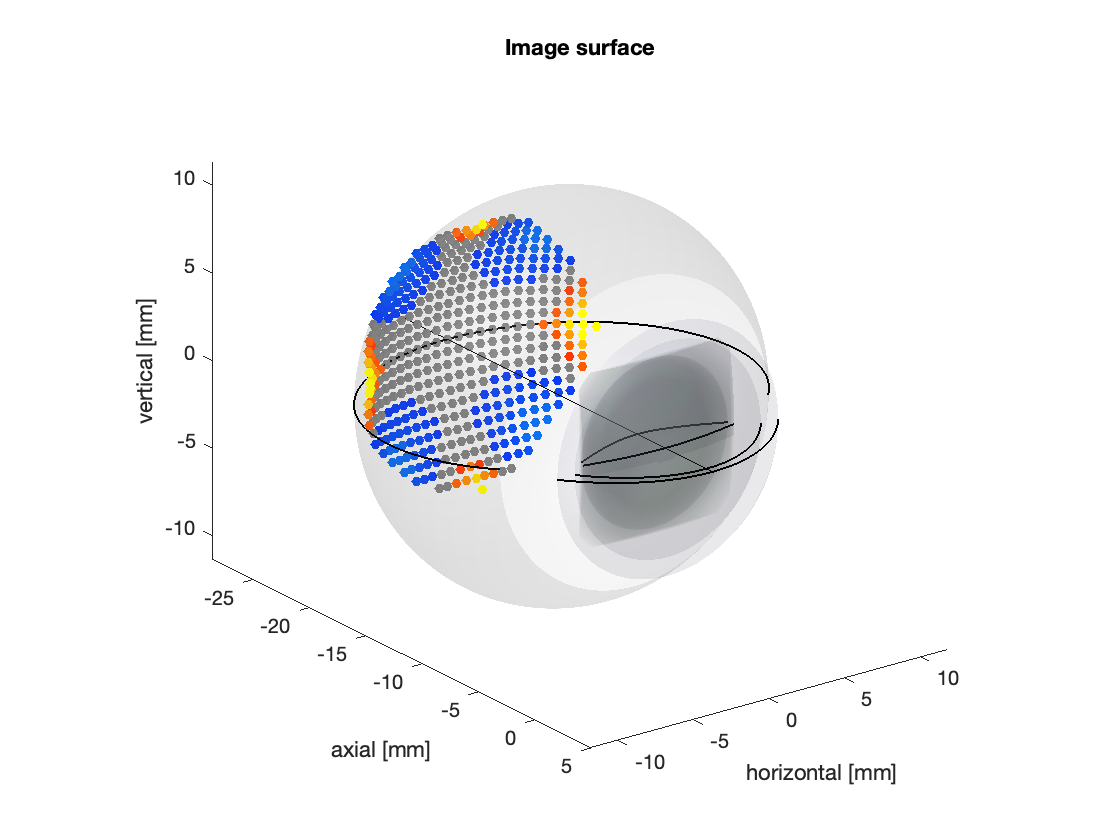

scatter3(iFP(1,:),iFP(2,:),iFP(3,:),25,cFP,'o','filled');
view([53.3 21.8])

Color scale expresses the relative refractive error (in diopters) at each retinal location:

- Gray: refractive error less than 0.1 D

- Red (0) --> Yellow (–1): relative myopia

- Blue (0) --> aqua (1): relative hyperopia

Plot the object surface

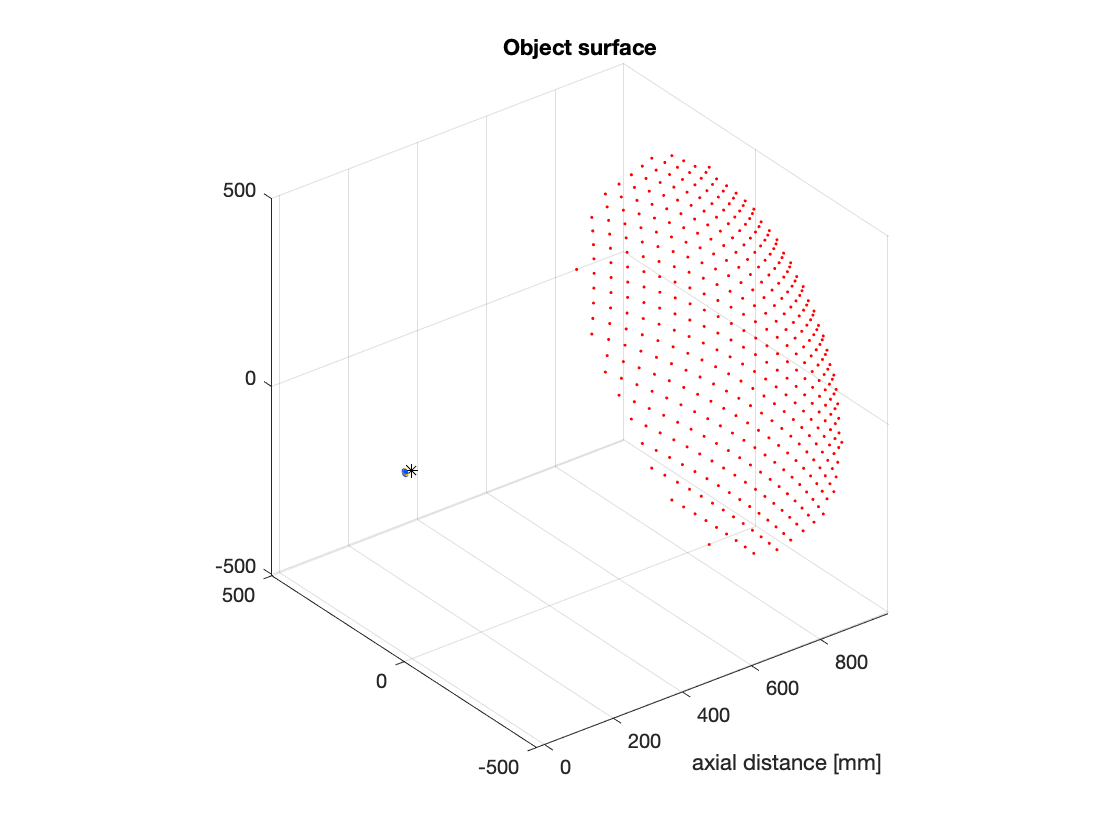

figure
scatter3(iFP(1,:),iFP(2,:),iFP(3,:),1,cFP,'.')
hold on
scatter3(eFP(1,:),eFP(2,:),eFP(3,:),1,'r','.')
plot3(principalPoint(1),principalPoint(2),principalPoint(3),'*k')
xlabel('axial distance [mm]')
title('Object surface')
xlim([-25 1000]);
axis equal

Try adjusting the accommodation parameter of the model eye and re-running the demo. You will observe that changes in the overal accommodative state of the eye have only a small effect upon the relative accommodation of the retinal periphery.